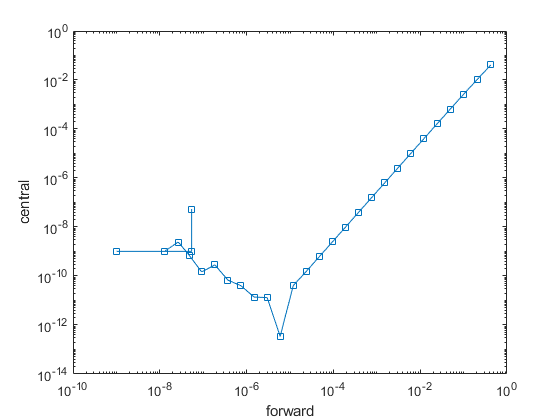

A = zeros(3,32);
for e = (-1:-1:-32)
    h = power(2.0,e);
    A(1,-e) = h;
    A(2,-e)=test1(h);
    A(3,-e)=test2(h);
end

loglog(A(2,1:32), A(3,1:32), '-s')
xlabel('forward')
ylabel('central')

Make forward divided difference

function [t] = test1(a)
m = f1(a);
s = cos(1);
t = abs(m-s)/abs(s);
end

function c = f1(x)
c = (sin(1+x)-sin(1))/x;
end


Make central divided difference

function [t] = test2(a)
m = f2(a);
s = cos(1);
t = abs(m-s)/abs(s);
end

function c = f2(x)
c = (sin(1+x)-sin(1-x))/(2*x);
end

Analysis:

looking at the graph, y(central divided difference) is more accurate but as h gets smaller the difference between x and y becomes smaller.